# Løsning til 2017 eksamen

## Opgave 1

## Opgave 2

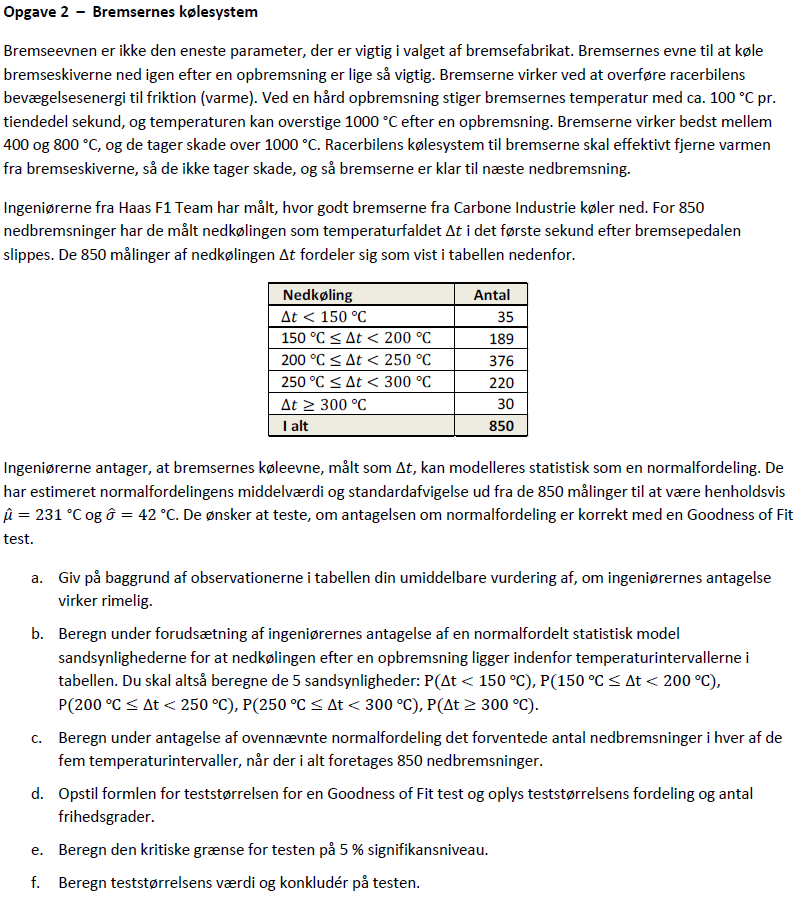

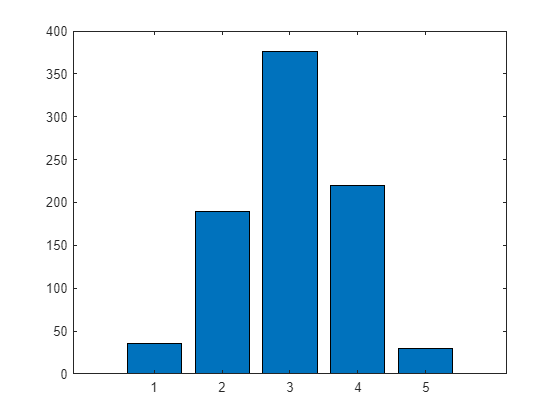

clc; clear all

% Opgave a

% Data fra opgaven
sigma = 42;
mu = 231;


% Antal observeringer i tabellen
obs = 1:1:5;
delta_ts = [35, 189, 376, 220, 30];

% Bar plot og dist plot
figure;
bar(obs, delta_ts);



dist = makedist("Normal", "mu",mu, "sigma",sigma);

x = 0:1:400;

pd = pdf(dist,x)

pd =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


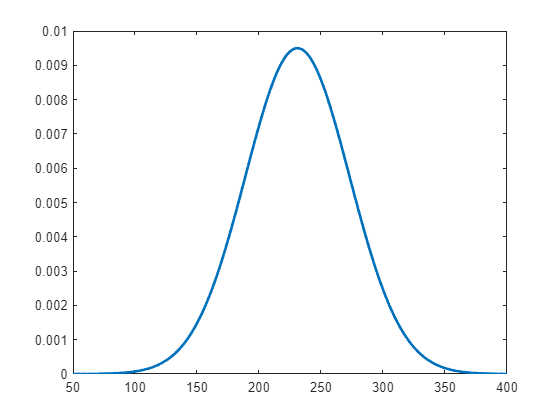


plot(x, pd, 'LineWidth',2), xlim([50, 400])

% Opgave b

% Mindre end 150C
p1 = normcdf(150, mu, sigma)

p1 = 0.0269

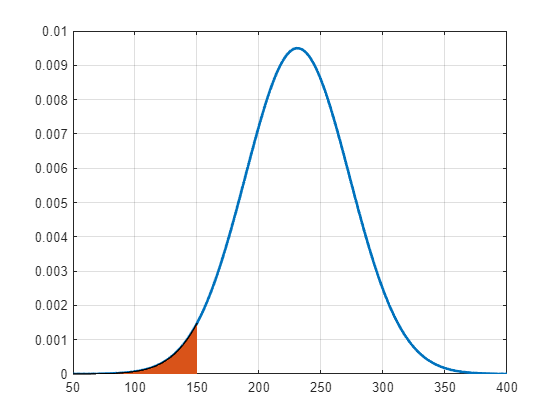


plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

area(x(1, 1:151), pd(1, 1:151))
hold off



% Mellem 150 og 200C
p2 = normcdf(200, mu, sigma) - p1

p2 = 0.2033

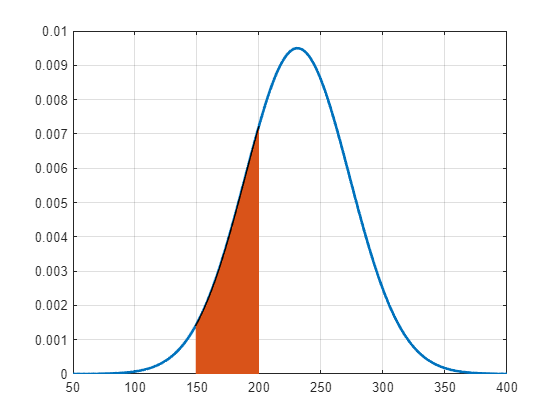


plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

area(x(1, 150:201), pd(1, 150:201))
hold off


% Mellem 200 og 250C
p3 = normcdf(250, mu, sigma) - normcdf(200, mu, sigma)

p3 = 0.4443

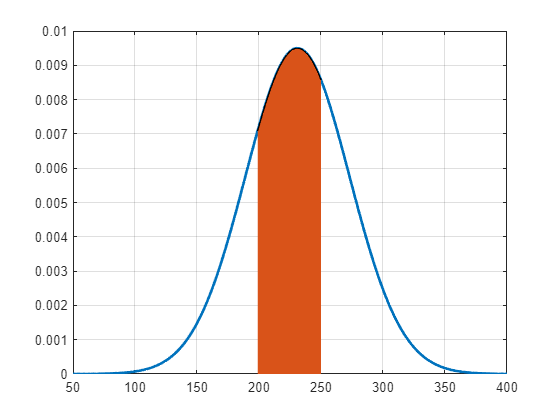

plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

area(x(1, 200:251), pd(1, 200:251))
hold off


% Mellem 250 og 300C
p4 = normcdf(300, mu, sigma) - normcdf(250, mu, sigma)

p4 = 0.2753

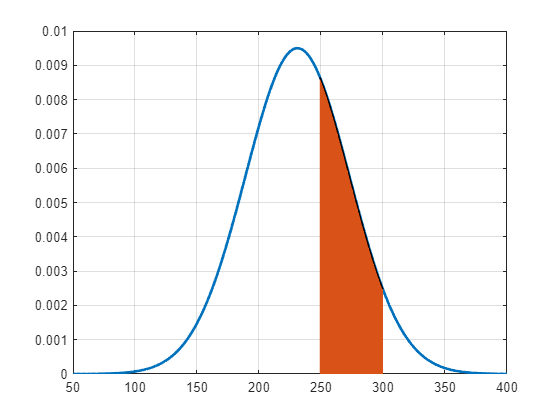


plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

area(x(1, 250:301), pd(1, 250:301))
hold off



% Mere end 300C
p5 = 1 - normcdf(300, mu, sigma)

p5 = 0.0502

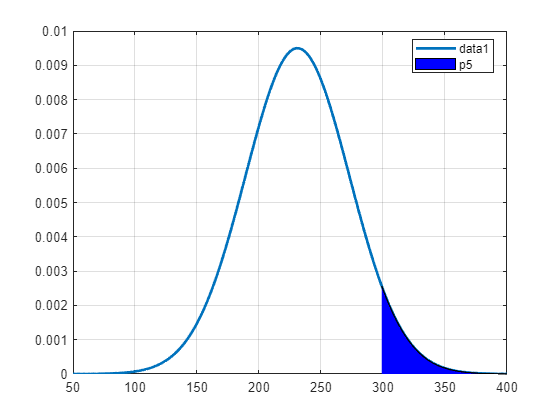


plot(x, pd, 'LineWidth',2), xlim([50, 400]), grid()
hold on

aa = area(x(1, 300:end), pd(1, 300:end), facecolor="b", DisplayName="p5");
legend(Location="best")
hold off

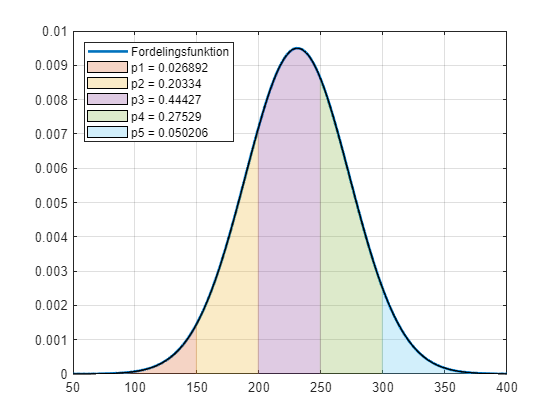


plot(x, pd, 'LineWidth',2, DisplayName="Fordelingsfunktion"), xlim([50, 400]), grid()
hold on
a1 = area(x(1, 1:151), pd(1, 1:151), DisplayName="p1 = " + p1);
a2 = area(x(1, 150:201), pd(1, 150:201), DisplayName="p2 = " + p2);
a3 = area(x(1, 200:251), pd(1, 200:251), DisplayName="p3 = " + p3);
a4 = area(x(1, 250:301), pd(1, 250:301), DisplayName="p4 = " + p4);
a5 = area(x(1, 300:end), pd(1, 300:end), DisplayName="p5 = " + p5);
alpha([a1,a2,a3,a4,a5], 0.25)
legend(Location="northwest")
hold off

clc; clear all;

% Funktion til fill i arealer under plots
% Inputs er plottet, dets interval x, funktionsværdierne f(x), liste med
% navne over invervallernes værdier, og selve værdierne



% Opgave c
ps = [p1, p2, p3, p4, p5];
n_obs = 850;

forv_obs = ps*n_obs

forv_obs =    22.8582  172.8358  377.6333  233.9974   42.6753




disp(table(delta_ts', ps', forv_obs', VariableNames=["Observerede værdier", "Sandsynligheder", "Forventede værdier"]))

    Observerede værdier    Sandsynligheder    Forventede værdier
    ___________________    _______________    __________________

             35               0.026892              22.858      
            189                0.20334              172.84      
            376                0.44427              377.63      
            220                0.27529                 234      
             30               0.050206              42.675      





% Opgave d

## Opgave 3